## Working with 2D Medical Images 

backXray=medicalImage('back view02.dcm')

backXray =   medicalImage with properties:

          Pixels: [3028×1676 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


img_2= extractFrame(backXray,1);
D2.Value_mm=D2.Value*backXray.PixelSpacing(1)

D2 = struct with fields:
    Position: [2×2 double]
       Value: 251.4355
    Value_mm: 34.9495


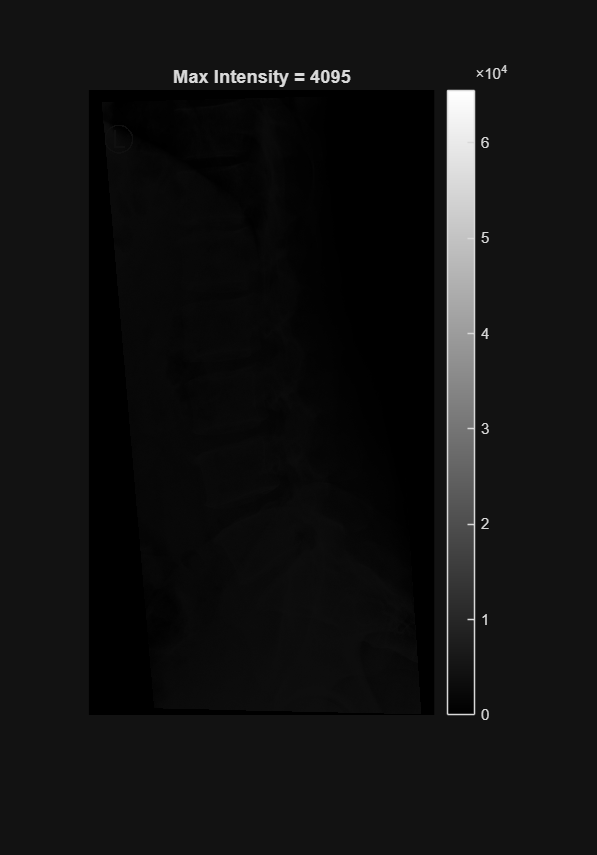

% Extract the image

maxVal = max(img_2, [], "all");
% View using imshow
figure
imshow(img_2)
title("Max Intensity = " + maxVal)
colorbar

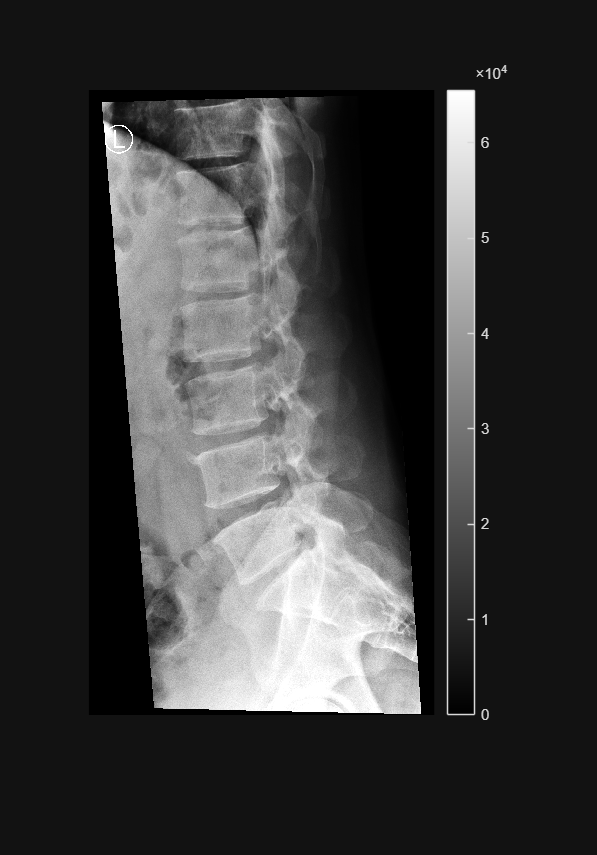

imgAdj = imadjust(img_2);
figure
imshow(imgAdj)
colorbar

info = medicalImage("back view02.dcm");
spacing = info.PixelSpacing;
disp(spacing)

    0.1390    0.1390

